# Plot

UWCC Structural Analysis: Heerod Sahraei

Run after Main.mlx

## Moment and Shear

### Inputs

toPlot = ["RaceStands", "MaleTandem","FemaleTandem",];
displayName = ["Race Stands", "MaleTandem","FemaleTandem"];
colors = ["red","blue","green"];

### Diagrams

close;
hold on;
for i = 1:numel(toPlot)
    V = LoadCases.(toPlot(i)).ShearDistribution;
    
    plot(xInterp,V,'Color',colors(i),'LineWidth',2,'DisplayName',displayName(i));
    xlim([xInterp(1) xInterp(end)]);
    title('Shear Diagram');
    xlabel('Longitudinal Station (in.)');
    ylabel('Shear (lbs.)');
    legend("Location","southeast");
end
figure;
hold on;
for i = 1:numel(toPlot)
    M = LoadCases.(toPlot(i)).MomentDistribution;
    
    plot(xInterp,M,'Color', colors(i), 'LineWidth', 2, 'DisplayName',displayName(i));
    xlim([xInterp(1) xInterp(end)]);
    title('Moment Diagram');
    xlabel('Longitudinal Station (in.)');
    ylabel('Bending Moment (lbs.*in.)');
    legend("Location","southeast");
    
end

## FBD

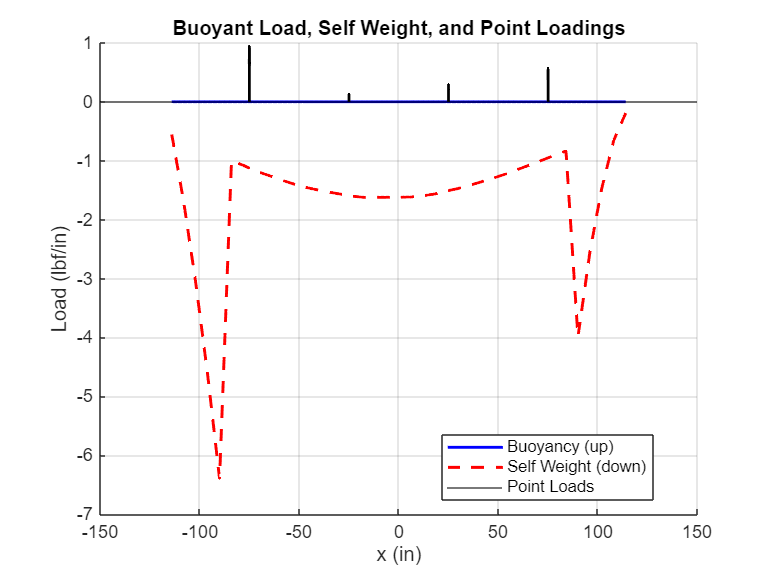

caseName = caseNames(1);

P = LoadCases.(caseName{:}).PointLoads;
buoyancy = LoadCases.(caseName{:}).BuoyantDistribution;

figure('Color','w'); hold on; grid on;
plot(xInterp, buoyancy, 'b-', 'LineWidth',1.6);
plot(xInterp, selfWeightInterp, 'r--', 'LineWidth',1.6);
yline(0,'k-');

for i = 1:(numel(P)/2)
    x0 = P(1,i);
    Pmag = P(2,i);
    quiver(x0, 0, 0, Pmag/200, 0, 'MaxHeadSize',1, 'Color','k', 'LineWidth',1.5); % represent paddlers as arrows
end

xlabel('x (in)');
ylabel('Load (lbf/in)');
title('Buoyant Load, Self Weight, and Point Loadings');
legend('Buoyancy (up)','Self Weight (down)','Point Loads','Location','best');

## Cable Force Envelope